# ME 419 Solar Tracking Panel Control Term Project 

**Names:** Julia Fay, Aiden Taylor 

**Date:** 2024.3.20

**Class:** ME419

**Description: **The purpose of this file is to simulate the control of a solar tracking solar panel to compare to experimental behaviors found with testing. 

## System Properties 

% Visous damping coefficient 
b               = 10;               % [N*m*s/rad]
% Winding resistance
R               = 1;                % [Ω]
% Winding inductance
L               = 0.078e-3;         % [H]
% Rotor inertia
Jmotor          = 9.82e-7;          % [kg*m^2]
%Panel inertia 
Jpanel          = 5;                % [kg*m^2]
%Total inertia 
J               = Jmotor+Jpanel;    % [kg*m^2]
% Motor torque constant 
K_t             = 5;                % [N*m/A]
% Motor voltage constant 
K_v             = 5;                % [V*sec/rad]
% Radian to voltage conversion factor 
K_c             = 1/(0.5*pi());     % [V/rad]

## Block Diagram 

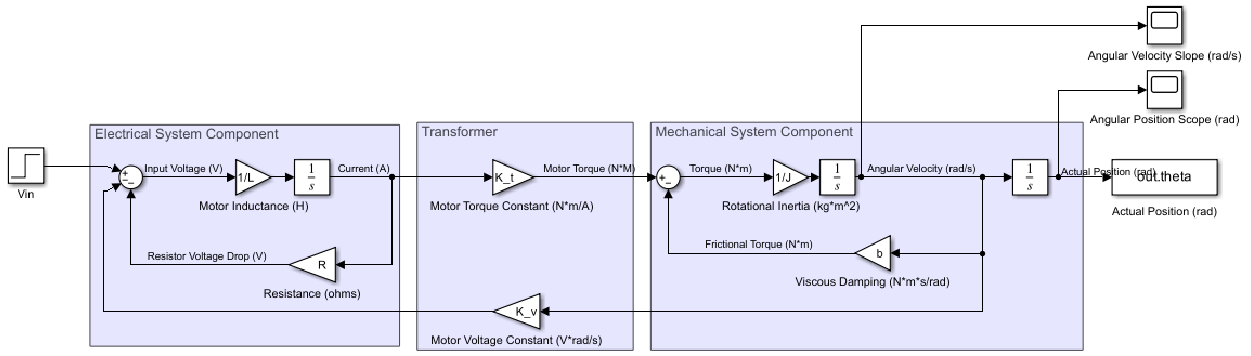

snapshotModel('ME419TermProj') %output simulink image

## Frictionless Simulation 

%Input A,B,C, and K matricies 
b = 0;

K1 = [11.42 -121.01];

A_new_1 = [0              1
    -(K1(1,1))      -(((R*b + K_v^2)/R*J)+K1(1,2))]

A_new_1 =          0    1.0000
  -11.4200   -3.9900



B = [0
     1];

C = [((K_v*K_c)/R*J) 0];

D = [0];

sys1_tf = tf(((K_v*K_c)/R*J),[1 ((R*b + K_v^2)/R*J) 0])

sys1_tf =
 
     15.92
  -----------
  s^2 + 125 s
 
Continuous-time transfer function.
Model Properties


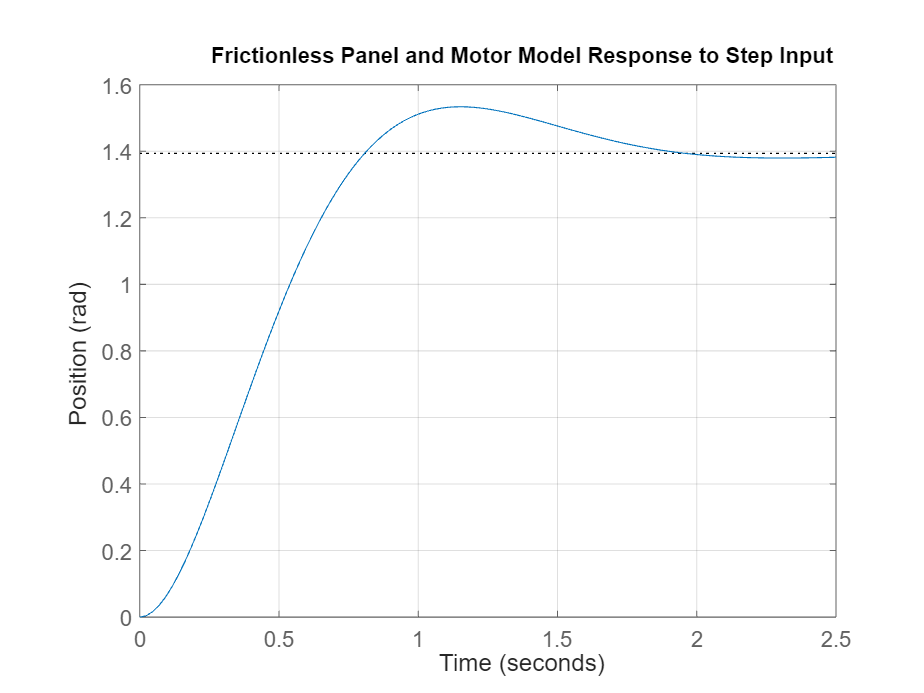


sys1 = ss(A_new_1,B,C,D);

figure; 
step(sys1)
xlabel("Time");
ylabel("Position (rad)");
title('Frictionless Panel and Motor Model Response to Step Input','FontSize',10,'FontWeight','bold');
grid on


%now try to simulate the system with friction using the K values calculated
%for the frictionless system
b = 10; 
K2 = [11.42 -121.01];

A_new_2 = [0              1
    -(K2(1,1))      -(((R*b + K_v^2)/R*J)+K2(1,2))]

A_new_2 =          0    1.0000
  -11.4200  -53.9900


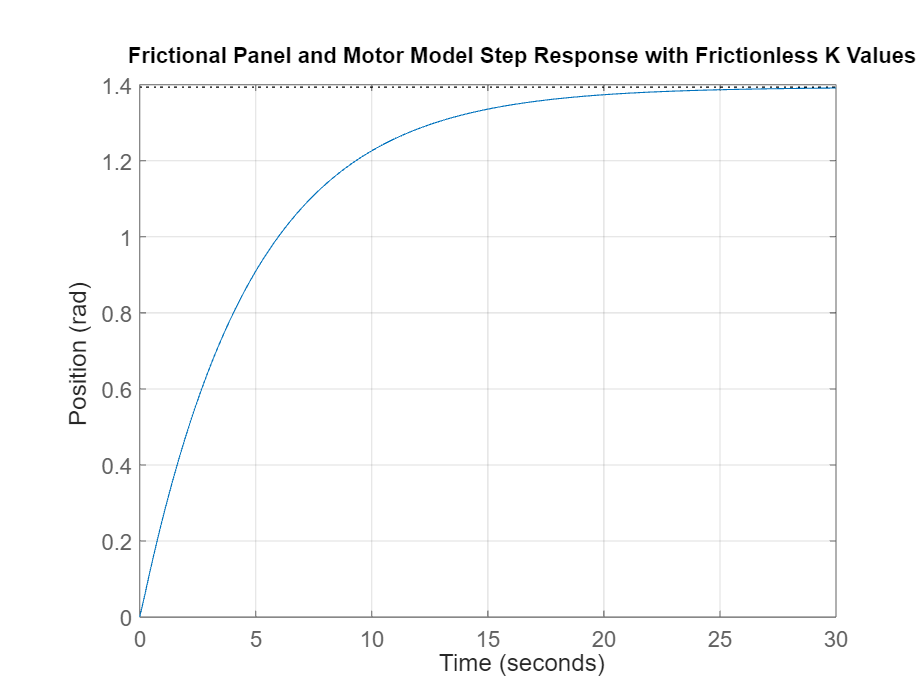


sys2 = ss(A_new_2,B,C,D);
step(sys2)
xlabel("Time");
ylabel("Position (rad)");
title('Frictional Panel and Motor Model Step Response with Frictionless K Values','FontSize',10,'FontWeight','bold');
grid on

## Friction Simulation 

%now reintroduce friction 
%Input Anew,B,C, and K matricies 
K3 = [11.42 -171.01];

A_new_3 = [0              1
    -(K3(1,1))      -(((R*b + K_v^2)/R*J)+K3(1,2))]

A_new_3 =          0    1.0000
  -11.4200   -3.9900



B1 = [0
     1];

C1 = [((K_v*K_c)/R*J) 0];

D1 = [0];

sys3_tf = tf(((K_v*K_c)/R*J),[1 ((R*b + K_v^2)/R*J) 0])

sys3_tf =
 
     15.92
  -----------
  s^2 + 175 s
 
Continuous-time transfer function.
Model Properties


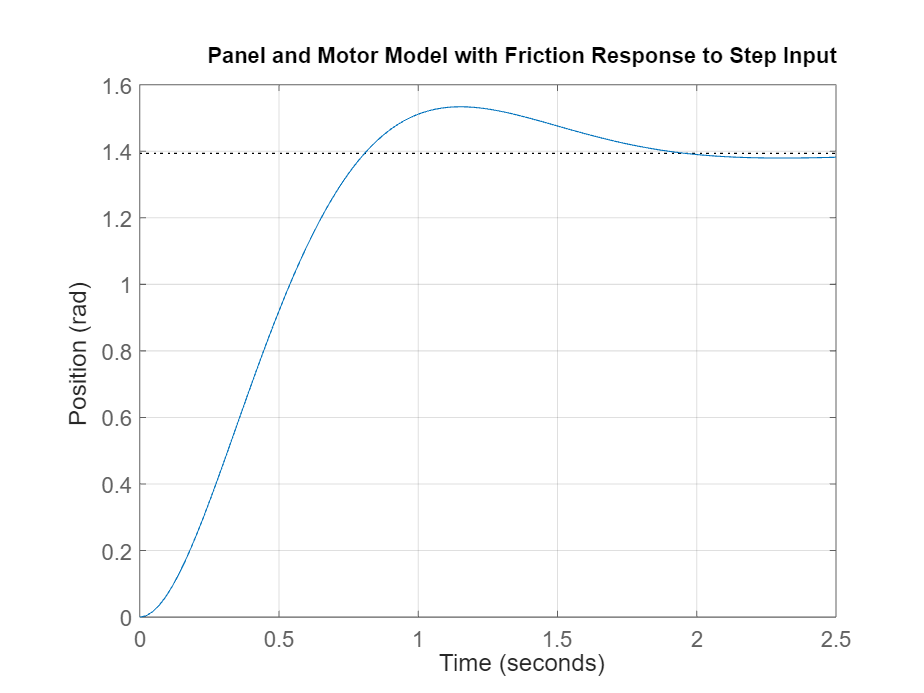

sys3 = ss(A_new_3,B1,C1,D1);

figure; 
step(sys3)
xlabel("Time");
ylabel("Position (rad)");
title('Panel and Motor Model with Friction Response to Step Input','FontSize',10,'FontWeight','bold');
grid on